Formler at lære udenad

1.1, 1.3, 1.7, 1,12b) og c), 1.12e 

simplified steady-flow thermal energy equation:

**Opgave 1.30**

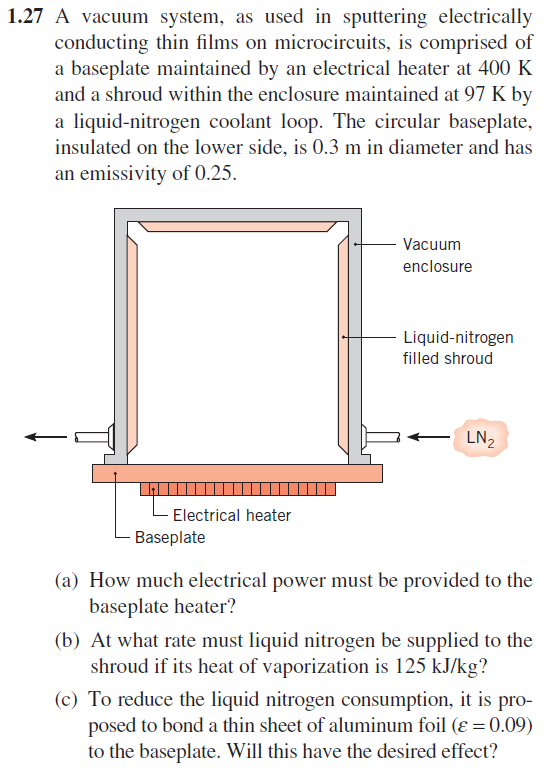

%a
T_heater = 400; %K
T_shroud = 97; %K
d=0.3; %m
epsilon = 0.25; %emesivitet
sigma = 5.67 * 10^-8; % J/K
A = pi*(d/2)^2;
q = A*epsilon * sigma * (T_heater^4 - T_shroud^4)

q = 25.5618


%b
l_f = 125000 %kJ/kg

l_f = 125000

%Q = m*L_f
m_dot = q/l_f %masse stræmmen kg/s

m_dot = 2.0449e-04


m_dot_hours = m_dot * 60 * 60

m_dot_hours = 0.7362

supplie 0,205 gram per s or 0,7362 kg per time

%c
epsilon_alu = 0.09

epsilon_alu = 0.0900

q_alu = q * (epsilon_alu/epsilon) % vi tager og divdere q med epsilon og ganger med epsilon alu istedet.

q_alu = 9.2022


m_dot = q_alu/l_f %masse stræmmen kg/s

m_dot = 7.3618e-05


m_dot_hours = m_dot * 60 * 60

m_dot_hours = 0.2650

**Opgave 1.48**

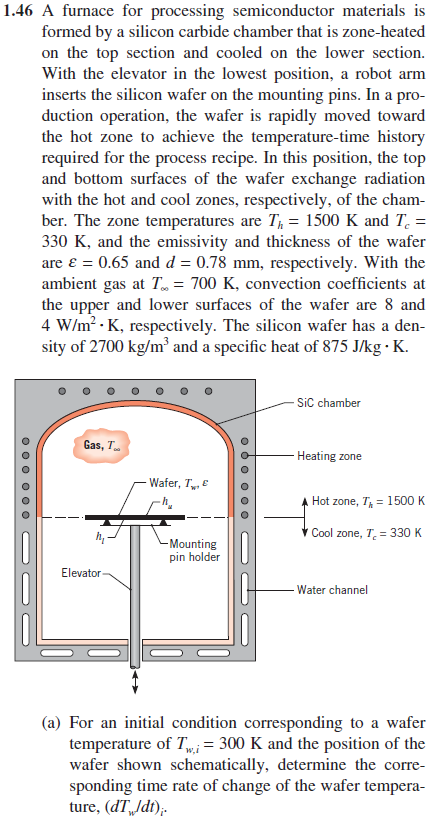

ASSUMPTIONS: 

(1) Wafer temperature is uniform, 

(2) Transient conditions when wafer is initially positioned, 

(3) Hot and cool zones have uniform temperatures, 

(4) Radiation exchange is between small surface (wafer) and large enclosure (chamber, hot or cold zone),

(5) Negligible heat losses from wafer to mounting pin holder.

clear all
T_h = 1500; %K
T_c = 330; %K
epsilon = 0.65; % from wafer
d = 0.78 *1e-3; %thickness of wafer %m
T_amb = 700 %K

T_amb = 700

sigma = 5.67 * 10^-8; % J/K
h_up = 8 % W/m^2*K

h_up = 8

h_low = 4 % W/m^2*K

h_low = 4


rho_SiC = 2700; % kg/m^3
c_p =  875; % J/kg*K

T_wi = 300; %K

q_con_h = h_up * (T_wi - T_amb) %convection above plate

q_con_h = -3200

q_con_l = h_low * (T_wi- T_amb) %convection below plate

q_con_l = -1600

q_rad_h = epsilon * sigma * (T_h^4 - T_wi^4) %radiation above plate

q_rad_h = 1.8628e+05

q_rad_l = epsilon * sigma * (T_c^4 - T_wi^4) %radiation below plate

q_rad_l = 138.5457


q_mark = - q_con_h - q_con_l + q_rad_h + q_rad_l

q_mark = 1.9122e+05

dTdt = q_mark / (rho_SiC * c_p * d)

dTdt = 103.7680

vpa(dTdt, 4)

$$ans = 103.8$$

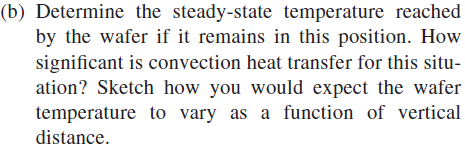

syms T_wi
q_con_h = h_up * (T_wi - T_amb); %convection above plate
q_con_l = h_low * (T_wi- T_amb); %convection below plate
q_rad_h = epsilon * sigma * (T_h^4 - T_wi^4); %radiation above plate
q_rad_l = epsilon * sigma * (T_c^4 - T_wi^4); %radiation below plate
q_mark = - q_con_h - q_con_l + q_rad_h + q_rad_l;
dTdt_eq = 0 == q_mark / (rho_SiC * c_p * d);

T_wi_steady = vpa(solve(dTdt_eq, T_wi),5)

$$T\_wi\_steady = \left(\begin{array}{c} 1250.8\\ 25.003-1276.3\,\mathrm{i}\\ 24.996+1276.3\,\mathrm{i}\\ -1300.8 \end{array}\right)$$

Her bruger vi den reele løsning der er positiv 1251 K